# IMU Calibration Walk Through

The following document serves as a walk-through of how to perform IMU Calibrations.  First, loading all the necessary data will be required.  

close all
clear all
clc

format longG

% Loading Accel Data
load('IMU_cal_data\x_up_accel.mat')
x_up_accel = accel;
load('IMU_cal_data\x_down_accel.mat')
x_down_accel = accel;
load('IMU_cal_data\y_up_accel.mat')
y_up_accel = accel;
load('IMU_cal_data\y_down_accel.mat')
y_down_accel = accel;
load('IMU_cal_data\z_up_accel.mat')
z_up_accel = accel;
load('IMU_cal_data\z_down_accel.mat')
z_down_accel = accel;

% Loading Gyro Data
load('IMU_cal_data\x_up_gyro.mat')
x_up_gyro = gyro;
load('IMU_cal_data\x_down_gyro.mat')
x_down_gyro = gyro;
load('IMU_cal_data\y_up_gyro.mat')
y_up_gyro = gyro;
load('IMU_cal_data\y_down_gyro.mat')
y_down_gyro = gyro;
load('IMU_cal_data\z_up_gyro.mat')
z_up_gyro = gyro;
load('IMU_cal_data\z_down_gyro.mat')
z_down_gyro = gyro;


## Plotting the Collected Data as an example

This section plots all the data collection requirements, makes nice plots for the thesis document.  

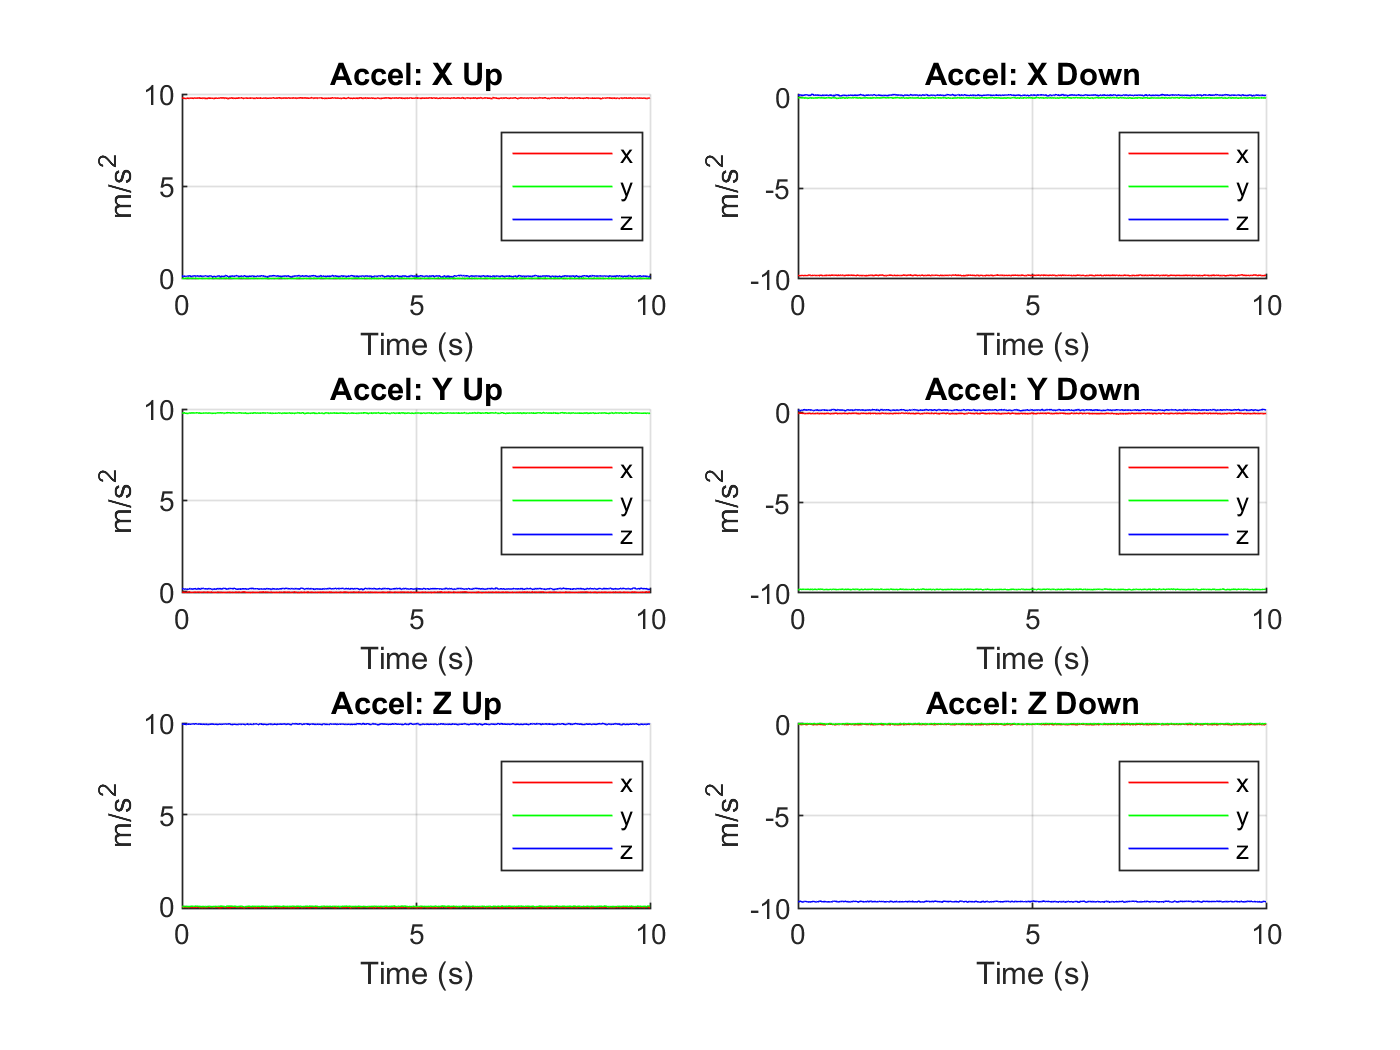

% Accel Data Plotting
t = 0 : (1/Fs) : (length(accel)-1)/Fs;

figure
subplot(3, 2, 1)
hold on
plot(t, x_up_accel(:,1), 'r', t, x_up_accel(:,2), 'g', t, x_up_accel(:,3), 'b')
title('Accel: X Up')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 2)
hold on
plot(t, x_down_accel(:,1), 'r', t, x_down_accel(:,2), 'g', t, x_down_accel(:,3), 'b')
title('Accel: X Down')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

subplot(3, 2, 3)
hold on
plot(t, y_up_accel(:,1), 'r', t, y_up_accel(:,2), 'g', t, y_up_accel(:,3), 'b')
title('Accel: Y Up')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 4)
hold on
plot(t, y_down_accel(:,1), 'r', t, y_down_accel(:,2), 'g', t, y_down_accel(:,3), 'b')
title('Accel: Y Down')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

subplot(3, 2, 5)
hold on
plot(t, z_up_accel(:,1), 'r', t, z_up_accel(:,2), 'g', t, z_up_accel(:,3), 'b')
title('Accel: Z Up')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 6)
hold on
plot(t, z_down_accel(:,1), 'r', t, z_down_accel(:,2), 'g', t, z_down_accel(:,3), 'b')
title('Accel: Z Down')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

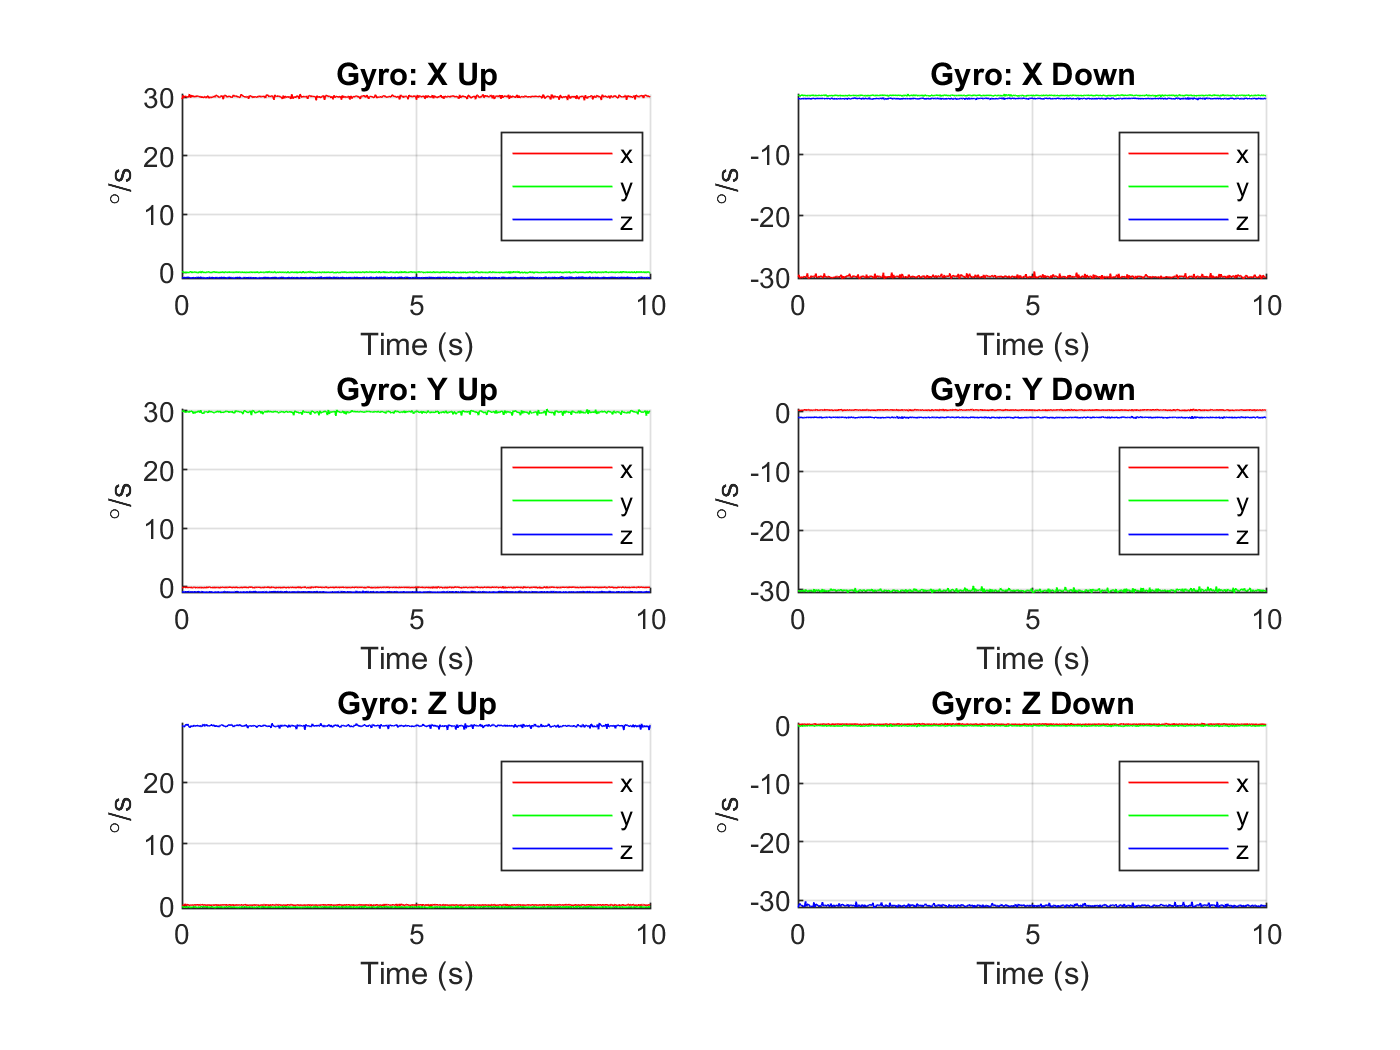

% Gyro Data Plotting

figure
subplot(3, 2, 1)
hold on
plot(t, x_up_gyro(:,1)*180/pi, 'r', t, x_up_gyro(:,2)*180/pi, 'g', t, x_up_gyro(:,3)*180/pi, 'b')
title('Gyro: X Up')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 2)
hold on
plot(t, x_down_gyro(:,1)*180/pi, 'r', t, x_down_gyro(:,2)*180/pi, 'g', t, x_down_gyro(:,3)*180/pi, 'b')
title('Gyro: X Down')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

subplot(3, 2, 3)
hold on
plot(t, y_up_gyro(:,1)*180/pi, 'r', t, y_up_gyro(:,2)*180/pi, 'g', t, y_up_gyro(:,3)*180/pi, 'b')
title('Gyro: Y Up')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 4)
hold on
plot(t, y_down_gyro(:,1)*180/pi, 'r', t, y_down_gyro(:,2)*180/pi, 'g', t, y_down_gyro(:,3)*180/pi, 'b')
title('Gyro: Y Down')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

subplot(3, 2, 5)
hold on
plot(t, z_up_gyro(:,1)*180/pi, 'r', t, z_up_gyro(:,2)*180/pi, 'g', t, z_up_gyro(:,3)*180/pi, 'b')
title('Gyro: Z Up')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off
subplot(3, 2, 6)
hold on
plot(t, z_down_gyro(:,1)*180/pi, 'r', t, z_down_gyro(:,2)*180/pi, 'g', t, z_down_gyro(:,3)*180/pi, 'b')
title('Gyro: Z Down')
xlabel('Time (s)')
ylabel('{\circ}/s')
grid on
legend('x', 'y', 'z', 'Location', 'Best')
hold off

## Solving for Fixed/Stability Bias

Solving for the fixed bias of the accelerometer and gyroscope.  

format shortg

% Accelerometer Fixed Bias
x_accel_mean = [mean(x_up_accel(:,1)), mean(x_down_accel(:,1))];
y_accel_mean = [mean(y_up_accel(:,2)), mean(y_down_accel(:,2))];
z_accel_mean = [mean(z_up_accel(:,3)), mean(z_down_accel(:,3))];

b_a_FB = (1/2) * [x_accel_mean(1) + x_accel_mean(2); y_accel_mean(1) + y_accel_mean(2); z_accel_mean(1) + z_accel_mean(2)];
row_names = {'X axis', 'Y axis', 'Z axis'};
column_names = {'Accel Bias (m/s^2)'};
T = array2table(b_a_FB, "RowNames", row_names, "VariableNames", column_names)

T = 3×1 table
              Accel Bias (m/s^2)
              __________________

    X axis        -0.012035     
    Y axis        -0.012878     
    Z axis          0.14146     



% Accelerometer Fixed Bias
x_gyro_mean = [mean(x_up_gyro(:,1)), mean(x_down_gyro(:,1))];
y_gyro_mean = [mean(y_up_gyro(:,2)), mean(y_down_gyro(:,2))];
z_gyro_mean = [mean(z_up_gyro(:,3)), mean(z_down_gyro(:,3))];

b_g_FB = (1/2) * [x_gyro_mean(1) + x_gyro_mean(2); y_gyro_mean(1) + y_gyro_mean(2); z_gyro_mean(1) + z_gyro_mean(2)];
row_names = {'X axis', 'Y axis', 'Z axis'};
column_names = {'Gyro Bias (rad/s)'};
T = array2table(b_g_FB, "RowNames", row_names, "VariableNames", column_names)

T = 3×1 table
              Gyro Bias (rad/s)
              _________________

    X axis        0.0020528    
    Y axis       -0.0031136    
    Z axis        -0.016177    


save('IMU_Cal_Const_Error_Sources.mat', "b_a_FB", "b_g_FB")

## ;Calculating the Misalignment Matrix

% Accelerometer Misalignment Matrix
    % via https://www.wolframalpha.com/widgets/view.jsp?id=e856809e0d522d3153e2e7e8ec263bf2
g = 9.7918; % Acceleration due to gravity in Prescott AZ, where Calibration was performed
% g = 9.80772; % gravity in Minot, ND

format shortg

% Scale Factor Terms
s_a_x = (1/(2*g)) * (x_accel_mean(1) - x_accel_mean(2)) - 1;
s_a_y = (1/(2*g)) * (y_accel_mean(1) - y_accel_mean(2)) - 1;
s_a_z = (1/(2*g)) * (z_accel_mean(1) - z_accel_mean(2)) - 1;

% Off-Diagonal Terms
m_a_yx = (1/(2*g)) * (mean(x_up_accel(:,2)) - mean(x_down_accel(:,2)));
m_a_zx = (1/(2*g)) * (mean(x_up_accel(:,3)) - mean(x_down_accel(:,3)));

m_a_xy = (1/(2*g)) * (mean(y_up_accel(:,1)) - mean(y_down_accel(:,1)));
m_a_zy = (1/(2*g)) * (mean(y_up_accel(:,3)) - mean(y_down_accel(:,3)));

m_a_xz = (1/(2*g)) * (mean(z_up_accel(:,1)) - mean(z_down_accel(:,1)));
m_a_yz = (1/(2*g)) * (mean(z_up_accel(:,2)) - mean(z_down_accel(:,2)));

% Piece Together the Misalignment Matrix
M_a = [s_a_x, m_a_xy, m_a_xz; m_a_yx, s_a_y, m_a_yz; m_a_zx, m_a_zy, s_a_z];
M_a

M_a =   -0.00026808    0.0015169    -0.002171
    0.0020504  -0.00026798   -0.0014299
    0.0003796     0.001511   0.00029024



% Gyroscope Misalignment Matrix
w_test = 30 * pi/180;

% Scale Factor Terms
s_g_x = (1/(2*w_test)) * (x_gyro_mean(1) - x_gyro_mean(2)) - 1;
s_g_y = (1/(2*w_test)) * (y_gyro_mean(1) - y_gyro_mean(2)) - 1;
s_g_z = (1/(2*w_test)) * (z_gyro_mean(1) - z_gyro_mean(2)) - 1;

% Off-Diagonal Terms
m_g_yx = (1/(2*w_test)) * (mean(x_up_gyro(:,2)) - mean(x_down_gyro(:,2)));
m_g_zx = (1/(2*w_test)) * (mean(x_up_gyro(:,3)) - mean(x_down_gyro(:,3)));

m_g_xy = (1/(2*w_test)) * (mean(y_up_gyro(:,1)) - mean(y_down_gyro(:,1)));
m_g_zy = (1/(2*w_test)) * (mean(y_up_gyro(:,3)) - mean(y_down_gyro(:,3)));

m_g_xz = (1/(2*w_test)) * (mean(z_up_gyro(:,1)) - mean(z_down_gyro(:,1)));
m_g_yz = (1/(2*w_test)) * (mean(z_up_gyro(:,2)) - mean(z_down_gyro(:,2)));

% Piece Together the Misalignment Matrix
M_g = [s_g_x, m_g_xy, m_g_xz; m_g_yx, s_g_y, m_g_yz; m_g_zx, m_g_zy, s_g_z];
M_g

M_g =   -9.8011e-05   -0.0066715  -0.00018718
    0.0073402  -0.00075136      -0.0011
   0.00030068    0.0014204   0.00032253


save('IMU_Cal_Const_Error_Sources.mat', "M_a", "M_g", '-append')

## Detrend the Data

% % I don't have Quiescent Data, but we will fake it for now
% accel = [detrend(z_up_accel(:,1))'; detrend(z_up_accel(:,2))'; detrend(x_up_accel(:,3))'];
% gyro = [detrend(z_up_gyro(:,1))'; detrend(z_up_gyro(:,2))'; detrend(x_up_gyro(:,1))'];
% 
% % Plot Example Quisecent Data
% figure
% plot(t, accel(1,:), 'r')
% title('X Axis Accel:  Quiesecent Data')
% xlabel('Time (s)')
% ylabel('m/s^2')
% grid on
% fprintf('X Accel Variance:    %4.8f \n', var(accel(1,:)))
% fprintf('X Accel Std Dev:     %4.8f \n', sqrt(var(accel(1,:))))

## One Sided PSD, No Windowing

Lets use the DFT (radix-2 FFT) to do so

% % Zero Pad the Data such that L = 2^N
% L = length(accel(1,:));
% n = 0; N = 0;
% 
% while (N < L)
%     n = n + 1;
%     N = 2^n;
% end
% 
% accel_z = [accel, zeros(3, (N - L))];
% gyro_z = [gyro, zeros(3, (N - L))];
% 
% % Calculate the FFT of the signals
% FFT_accel = [fft(accel_z(1,:)); fft(accel_z(2,:)); fft(accel_z(3,:))];
% FFT_gyro = [fft(gyro_z(1,:)); fft(gyro_z(2,:)); fft(gyro_z(3,:))];
% 
% Pxx_accel = [abs(FFT_accel(1,:)); abs(FFT_accel(2,:)); abs(FFT_accel(3,:))];
% Pxx_gyro = [abs(FFT_gyro(1,:)); abs(FFT_gyro(2,:)); abs(FFT_gyro(3,:))];
% 
% Pxx_accel = (1/N) .* Pxx_accel;
% Pxx_gyro = (1/N) .* Pxx_gyro;
% 
% % Plot Data
% Ts = 1 / Fs;
% df = 1 / Ts;
% f = linspace(0, 25, N);
% 
% figure
% %subplot(3,1,1)
% plot(f, Pxx_accel(1,:), 'r')
% title('PSD of x accel')
% xlabel('f (Hz)')
% ylabel('(mg)/sqrt(Hz)')
% grid on

## PSD via "pwlech"

% % Caving into the pre-built MTLAB function for comparison
% [P_welch, f_welch] = pwelch(accel(1,:), 128, [], [], Fs,  'onesided');
% figure
% plot(f_welch, P_welch)
% figure
% pwelch(accel(1,:), 128, [], [], Fs,  'onesided')

## Allan Variance Plot

I was going to try to build this one from scratch, but after reading the details on it, I decided not to. 

% % Allan Variance Deviation Plot for the Accelerometer
% for ii = 1 : 3
%     [avar, tau] = allanvar(accel(ii,:), 'octave', Fs);
%     tau_accel(ii,:) = tau;
%     avar_accel(ii,:) = avar;
%     
%     [avar, tau] = allanvar(gyro(ii,:), 'octave', Fs);
%     tau_gyro(ii,:) = tau;
%     avar_gyro(ii,:) = avar;
% end
% 
% figure
% hold on
% % subplot(3,1,1)
% loglog(tau_accel(1,:), avar_accel(1,:), 'r')
% title('Allan Deviation Plot: X axis, accel')
% xlabel('Averaging Time (\tau)')
% ylabel('\sigma')
% grid on
% % subplot(3,1,2)
% % loglog(tau_accel(2,:), avar_accel(2,:), 'g')
% % title('Allan Deviation Plot: Y axis, accel')
% % xlabel('Frequency (Hz)')
% % ylabel('PSD ((m/s^2)/Hz')
% % grid on
% % subplot(3,1,3)
% % loglog(tau_accel(3,:), avar_accel(3,:), 'b')
% % title('Allan Deviation Plot: Z axis, accel')
% % xlabel('Frequency (Hz)')
% % ylabel('PSD ((m/s^2)/Hz')
% % grid on
% % hold off
% 
% figure
% % subplot(3,1,1)
% loglog(tau_gyro(1,:), avar_gyro(1,:), 'r')
% title('Allan Deviation Plot: X axis, gyro')
% xlabel('Averaging Time (\tau)')
% ylabel('\sigma')
% grid on
% % subplot(3,1,2)
% % loglog(tau_gyro(2,:), avar_gyro(2,:), 'g')
% % title('Allan Deviation Plot: Y axis, gyro')
% % xlabel('Frequency (Hz)')
% % ylabel('PSD (({\circ}/h)/Hz')
% % grid on
% % subplot(3,1,3)
% % loglog(tau_gyro(3,:), avar_gyro(3,:), 'b')
% % title('Allan Deviation Plot: Z axis, gyro')
% % xlabel('Frequency (Hz)')
% % ylabel('PSD (({\circ}/h)/Hz')
% % grid on
% % hold off

## AutoCorrelation

% % AutoCorrelation of the Accelerometer and Gyroscope
% 
% N = length(accel(1,:));
% 
% for ii = 1 : 3 % for each row of data
%     for k = 1 : N % each index of R_xx
%         
%         %  Zero Pad each vector of data
%         a_k = [zeros(1,(k-1)), accel(ii,:)];
%         a = [accel(ii,:), zeros(1,(k-1))];
%         
%         % Autocorreclation of the Accelerometer Axis
%         Rxx_accel(ii, k) = (1/N) * sum(a_k .* a);
%         
%         %  Zero Pad each vector of data
%         g_k = [zeros(1,(k-1)), gyro(ii,:)];
%         g = [gyro(ii,:), zeros(1,(k-1))];
%         
%         % Autocorrelation of the Gyroscope Axis
%         Rxx_gyro(ii, k) = (1/N) * sum(g_k .* g);
%         
%     end
% end
% 
% figure
% hold on 
% % subplot(3,1,1)
% plot(t, Rxx_accel(1,:), 'r')
% title('X Accel AutoCorrelation')
% xlabel('Time (s)')
% ylabel('R_x_x')
% grid on
% 
% figure
% hold on 
% % subplot(3,1,1)
% plot(t, Rxx_accel(1,:), 'r')
% title('X Accel AutoCorrelation, Zoomed In')
% xlabel('Time (s)')
% xlim([0 0.25])
% ylabel('R_x_x')
% grid on
% % subplot(3,1,2)
% % plot(Rxx_accel(2,:), 'g')
% % title('Y Accel AutoCorrelation')
% % xlabel('???')
% % ylabel('R_x_x')
% % grid on
% % subplot(3,1,3)
% % plot(Rxx_accel(3,:), 'b')
% % title('Z Accel AutoCorrelation')
% % xlabel('???')
% % ylabel('R_x_x')
% % grid on
% % figure
% % hold on 
% % subplot(3,1,1)
% % plot(Rxx_gyro(1,:), 'r')
% % title('X Gyro AutoCorrelation')
% % xlabel('???')
% % ylabel('R_x_x')
% % grid on
% % subplot(3,1,2)
% % plot(Rxx_gyro(2,:), 'g')
% % title('Y Gyro AutoCorrelation')
% % xlabel('???')
% % ylabel('R_x_x')
% % grid on
% % subplot(3,1,3)
% % plot(Rxx_gyro(3,:), 'b')
% % title('Z Gyro AutoCorrelation')
% % xlabel('???')
% % ylabel('R_x_x')
% % grid on
% 
% % Display std devresults
% fprintf('X Accel Var:      %4.8f \n', Rxx_accel(1,1))
% fprintf('X Accel Std Dev:  %4.8f \n', sqrt(Rxx_accel(1,1)))
% 

## Histogram

% % Create Histograms for Accelerometer
% BW = 0.0001;
% 
% for ii = 1 : 3
%     figure
%     histogram(accel(ii,:), 'BinWidth', BW)
% end
% for ii = 1 : 3
%     figure
%     histogram(gyro(ii,:), 'BinWidth', BW)
% end